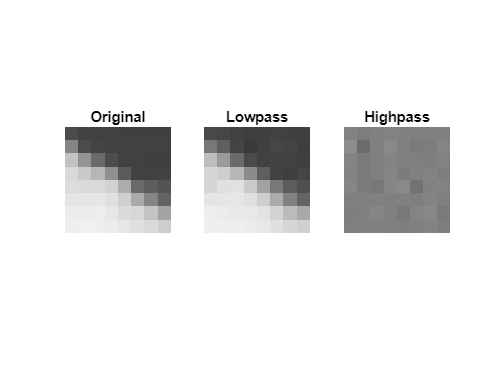

clear
clc

load('hall.mat');
hall_example = hall_gray(1:8,17:24);
figure
subplot(1,3,1);
imshow(hall_example); % original image
title('Original');
hall_example = double(hall_example) - 128;
hall_example_lp = DCTlp(hall_example)+128;
hall_example_hp = DCThp(hall_example)+128;
subplot(1,3,2);
imshow(uint8(hall_example_lp));
title('Lowpass');
subplot(1,3,3);
imshow(uint8(hall_example_hp));
title('Highpass');

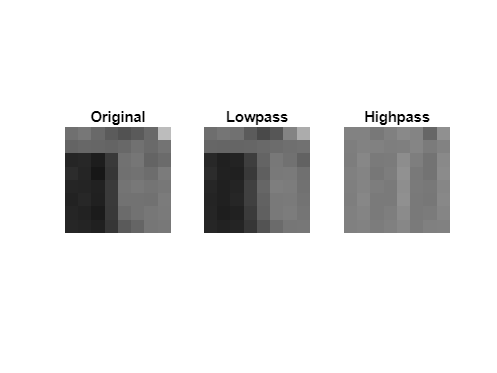


figure
hall_example = hall_gray(81:88,65:72);
figure
subplot(1,3,1);
imshow(hall_example); % original image
title('Original');
hall_example = double(hall_example) - 128;
hall_example_lp = DCTlp(hall_example)+128;
hall_example_hp = DCThp(hall_example)+128;
subplot(1,3,2);
imshow(uint8(hall_example_lp));
title('Lowpass');
subplot(1,3,3);
imshow(uint8(hall_example_hp));
title('Highpass');

function rslt = DCTlp(mat)
    rslt = dct2(mat);
    rslt(:,end-3:end) = 0;
    rslt = idct2(rslt);
end

function rslt = DCThp(mat)
    rslt = dct2(mat);
    rslt(:,1:4) = 0;
    rslt = idct2(rslt);
end